# run BDLMSC

clear
warning off all
data_dir = './dataset';
addpath(genpath(data_dir));
addpath(genpath('./util'))
addpath(genpath('./performance'))
% load dataset
load MSRC_v1.mat
load MSRC_v1_X_a.mat
nCluster = length(unique(truth));

% Setting parameters
% ORL: para.K = 50;para.lambda = 1e-1;
% Yale: para.K = 100;para.lambda = 1e0;
% MSRCV1: para.K = 50;para.lambda = 1e1;
% HW: para.K = 200;para.lambda = 1e-1;
% Reuters: para.K = 200;para.lambda = 1e1;
para.K = 50;
para.lambda = 1e1;
para

para = 包含以下字段的 struct :
         K: 50
    lambda: 10


% Run ELMSC
[Z,~,~] = ELMSC(X,X_a,para);
Aff = get_Aff(Z);
% Run spectral clustering
[groups] = spectral_clustering(Aff,nCluster);
% Computer metrics
[performance.ca,performance.nmi,performance.ar,performance.f1,~,~] = compute_metrics(truth,groups);
performance

performance = 包含以下字段的 struct :
     ca: 0.9905
    nmi: 0.9819
     ar: 0.9779
     f1: 0.9810


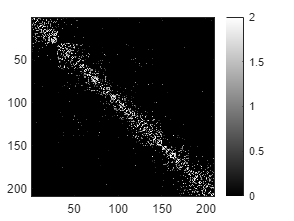

% plot affinity matrix
image(Aff,'CDataMapping','scaled')
colormap("gray")
colorbar